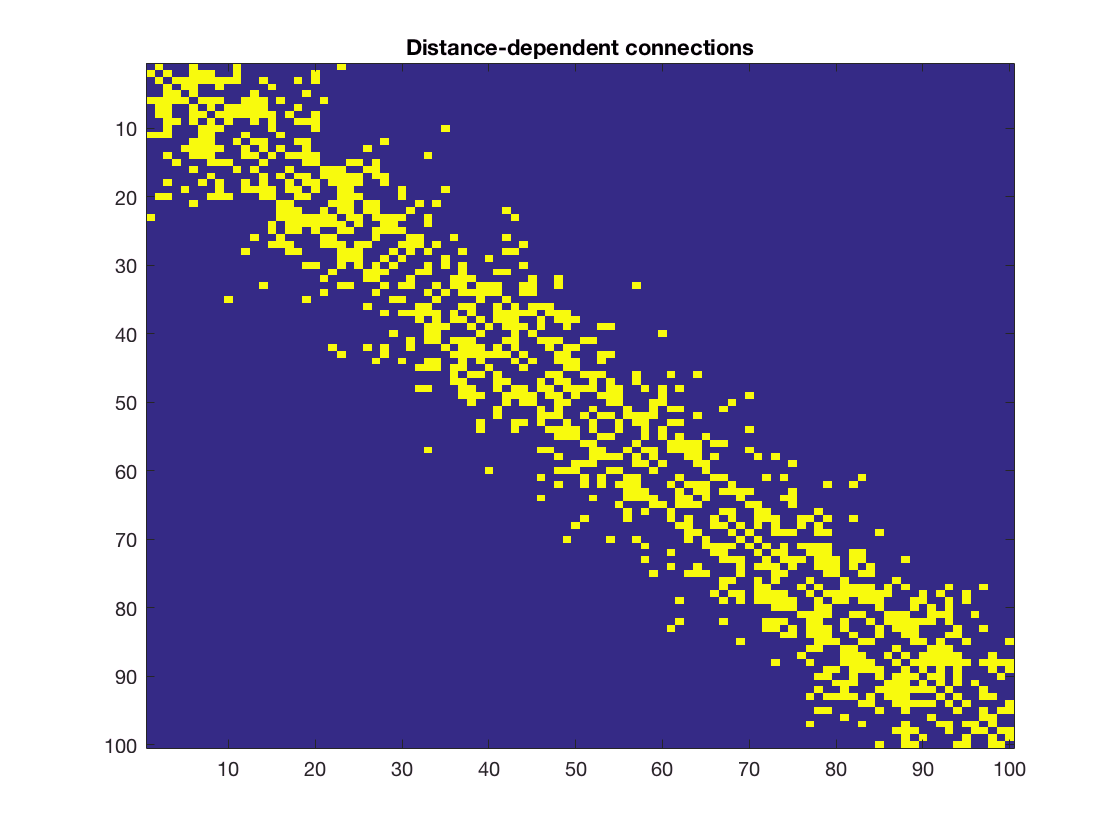


% Generate the connectivity matrix from given distribution decrease
% Euclidean distance, p(x,i,y,j)=p0*exp(-(x-i)^2/sigma_x -(y-j)^2/sigma_y);
% AUTAPSES (self-to-self connections) ARE REMOVED!

% sigma_x = d_x/n_x, where d - physical distance estimate, n - neurite length estimate
%                          d is esimated from Dupre and Yuste 2017, n - is estimated from dissociated cells (Charles David)

close all
clear

m=5;
n=20;


% parameters
p0=1;

% Endoderm
%sigma_x=0.73;
%sigma_y=0.73;

% Ectoderm
sigma_x=6;
sigma_y=5;


for i=1:1:1000

[A_pocket,A_prob]=M_pocket(m,n,p0,sigma_x,sigma_y);

A_graph=graph(A_pocket);       % create the graph out of adjacency matrix


if max(conncomp(A_graph))==1    
    break              % break the loop if all elements are parts of the same graph    
end

end


if max(conncomp(A_graph))==1
else
        disp('Did not find full connected graph yet');
end





imagesc(A_pocket);
title('Distance-dependent connections')

set(gca,'Fontsize',20)

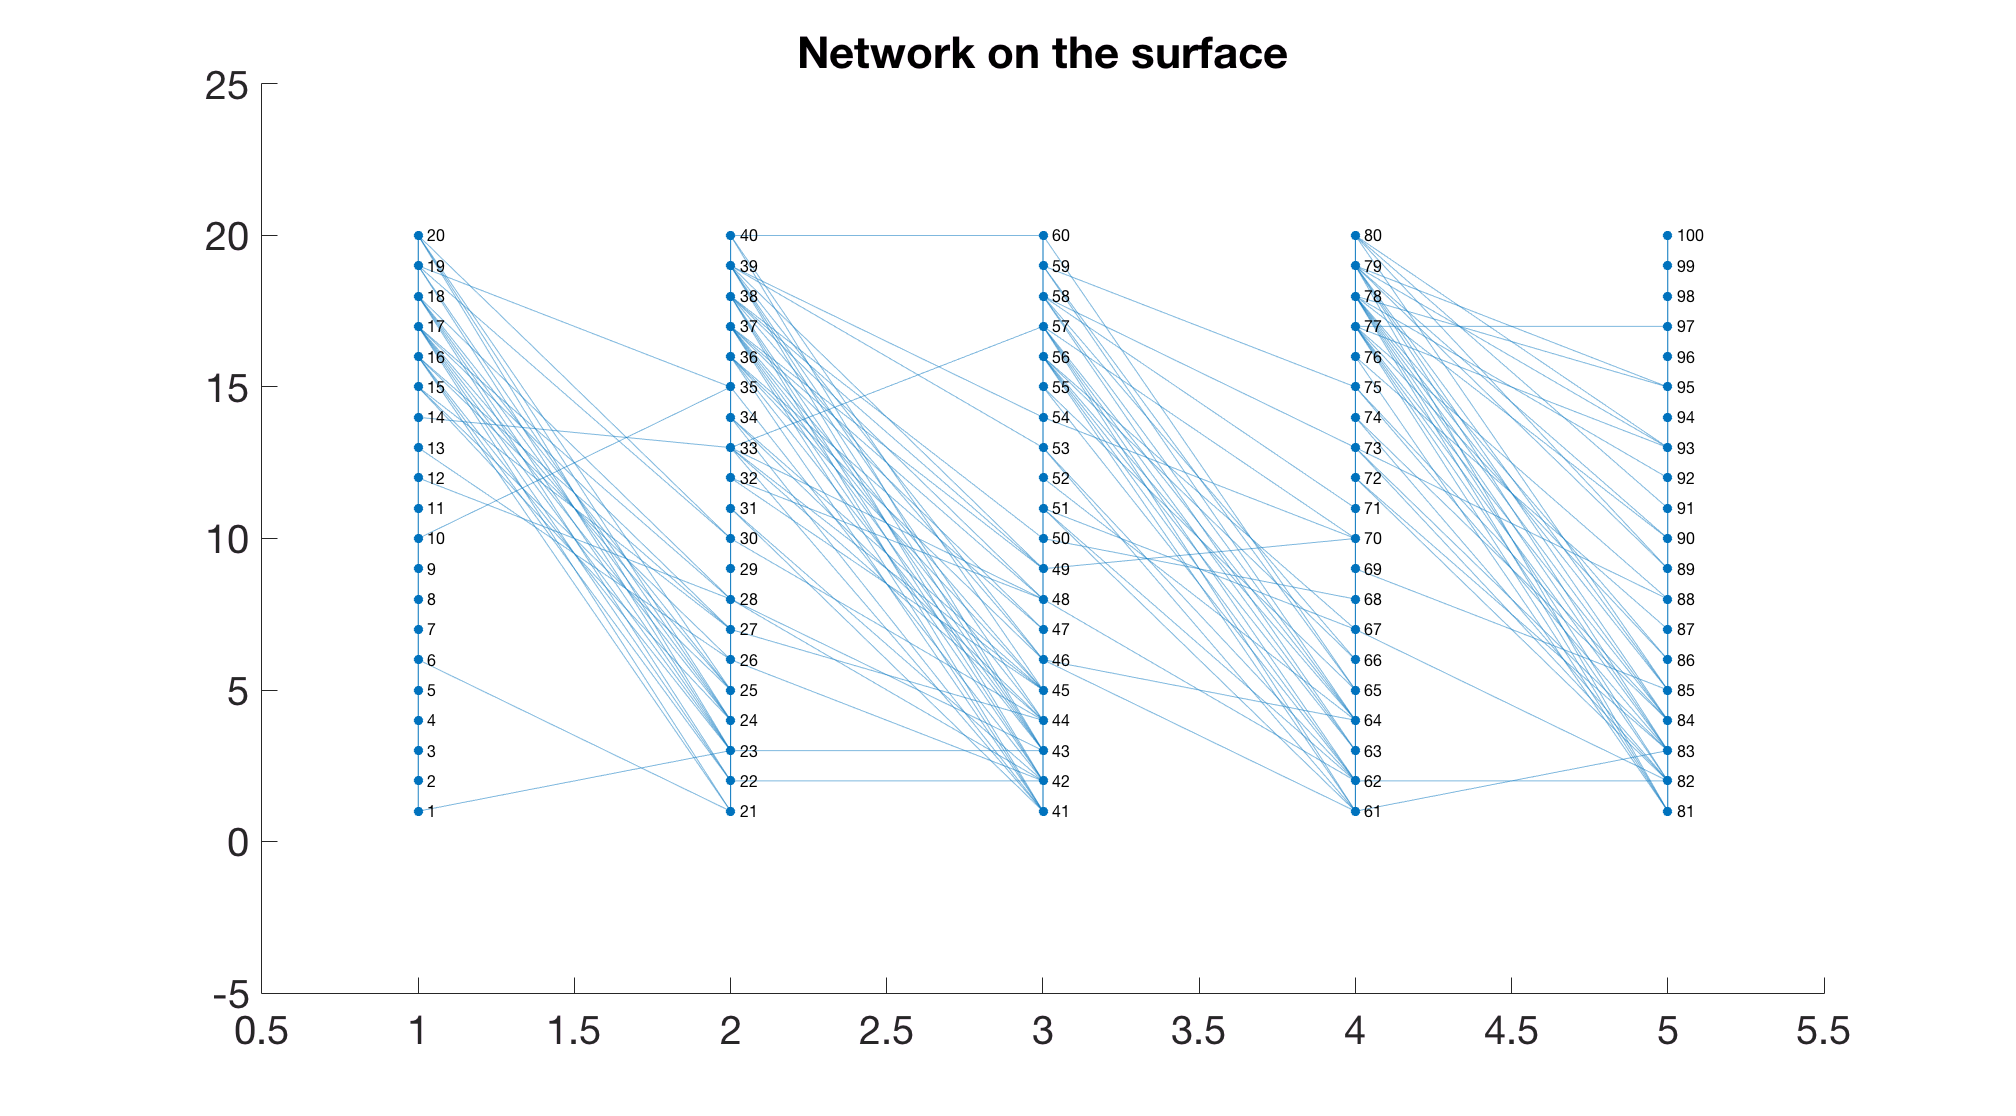

%% Generates the plot of the graph with the input stimuli PROBLEM - NOT ALL FIRED CELLS ARE SHOWN!!!

% graph parameters

figure('units','normalized','outerposition',[0 0 0.7 0.7]); % show figure window

%A_graph=graph(A_ind_dist);
A_graph=graph(A_pocket);

[X,Y]=meshgrid(1:m,1:n);        
x=reshape(X,[1,m*n]);
y=reshape(Y,[1,m*n]);
h=plot(A_graph,'Xdata',x,'Ydata',y);    %handle for the graph plot

box off

% Highlight the nodes
%highlight(h,firings(:,2),'Markersize',7,'Nodecolor','r')    
%highlight(h,stim_1,'Markersize',7,'Nodecolor','g')          

title('Network on the surface')
set(gca,'Fontsize',20)

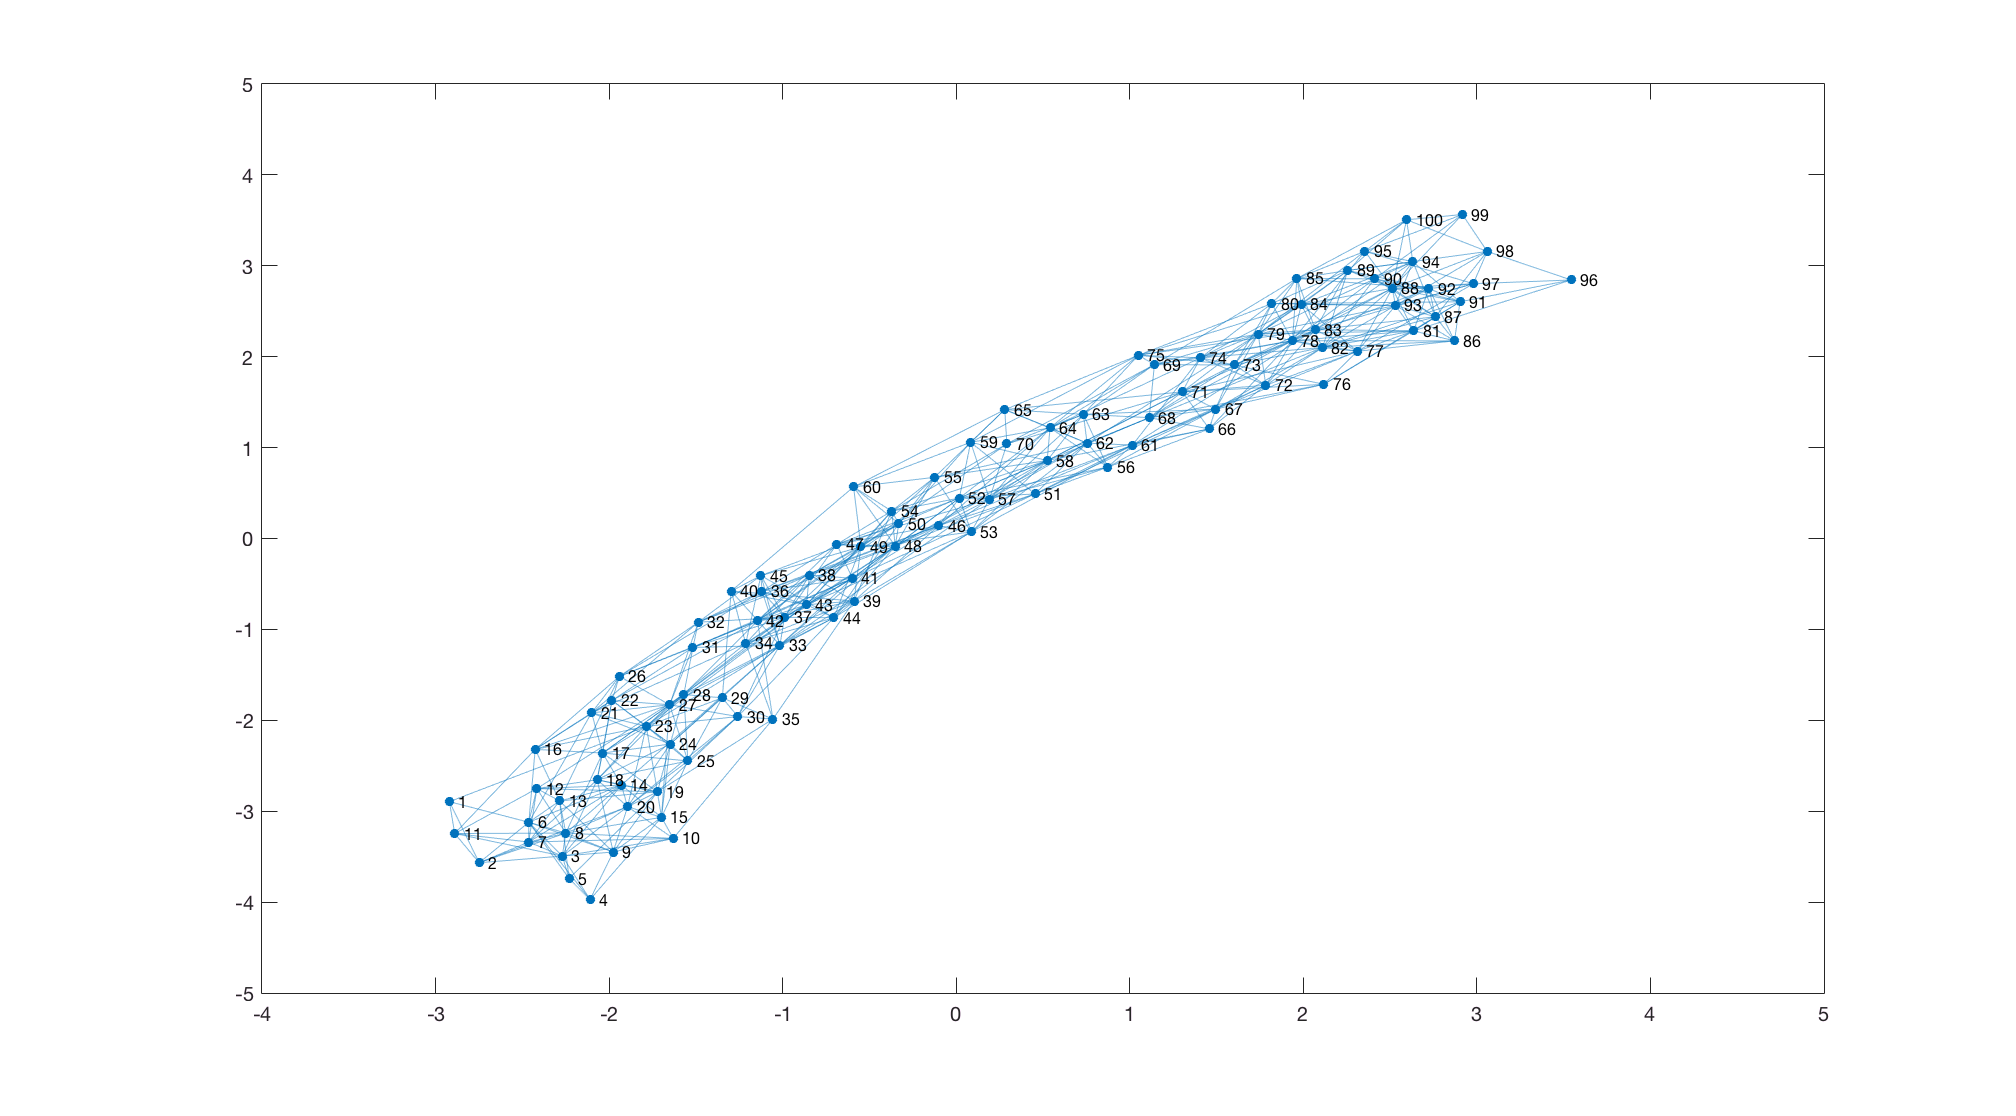

% Plot the graph in force style

A_biograph=graph(A_pocket);

plot(A_biograph,'Layout','force')